## Cvičení 5: - diferenciální rovnice

*Jak rešit rovnice, nebo soustavu rovnic ve které se nachází derivace?*

- **obyčejné diferenciální rovnice: podle jedné proměnné (čas)**

- parciální diferenciální rovnice: podle více proměných

Pohybové Newtonovy zákony:

        
$$\begin{array}{l}
\textrm{poloha}=\;\overrightarrow{r} \\
\textrm{rychlost}=\overrightarrow{v} =\frac{d}{\mathrm{d}t}\overrightarrow{r} \\
\textrm{zrychlení}=\;\overrightarrow{a} =\frac{d}{\mathrm{d}t}\overrightarrow{v} =\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\overrightarrow{r} \\
\textrm{síla}=\overrightarrow{F} =\overrightarrow{a} \cdot m=\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\overrightarrow{r} \cdot m
\end{array}$$


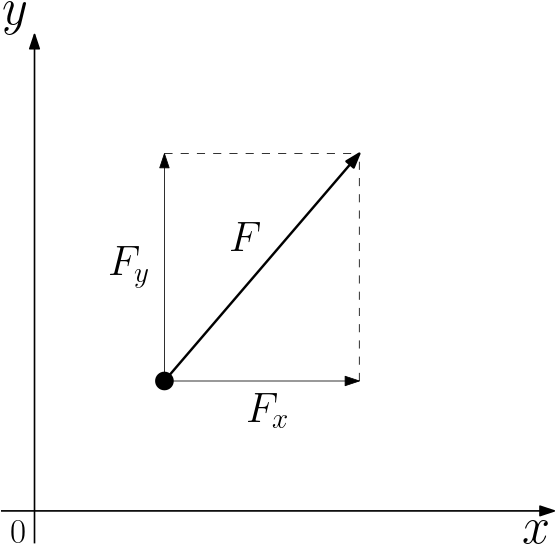

m = 0.5; % kg
uhel = 56; % °
F = 7; % N
pocatecni_vyska = 0;

% pocatecni podminky reseni
a = F/m;

uhel = (uhel/180)*pi; % převedení úhlu ve stupních na radiány

ax0 = a*cos(uhel);
ay0 = a*sin(uhel);

vx0 = 0;
vy0 = 0;

ry0 = pocatecni_vyska;
rx0 = 0;


Vzorec pro derivaci:


$$y\left(x\right)=\frac{\mathrm{d}}{\mathrm{d}x}f\left(x\right)=\lim_{h\;\to \;0} \left(\frac{f\left(x+h\right)-f\left(x\right)}{h}\right)$$


*Tady ale neznám hledanou funkci.. mám jen počáteční podmínky. Netuším jaký předpis má ta funkce, po které kámen poletí. → Takže půjdu krok po kroku z toho co vím. Jinými slovy neznám matematický předpis funkce, ale dokážu ji popsat právě soustavou rovnic. *

Rekurentní přepis:


$$y_{i+1} =y_i +h\cdot f\left(x_i \;,y_i \right)$$


vektor_velicin = [rx0, ry0, vx0, vy0, ax0, ay0];


$$\begin{array}{l}
\textrm{vektor}\;\textrm{velicin}=\;\left\lbrack \begin{array}{cccccc}
{\textrm{poloha}}_x  & {\textrm{poloha}}_y  & {\textrm{rychlost}}_x  & {\textrm{rychlost}}_y  & {\textrm{zrychlení}}_x  & {\textrm{zrychlení}}_y 
\end{array}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\left\lbrack \begin{array}{cccccc}
r_x  & r_y  & v_x  & v_y  & a_x  & a_y 
\end{array}\right\rbrack 
\end{array}$$


Pozor! Každá veličina ve vektoru veličin je také vektor. Takže ve výsledku máme matici!!

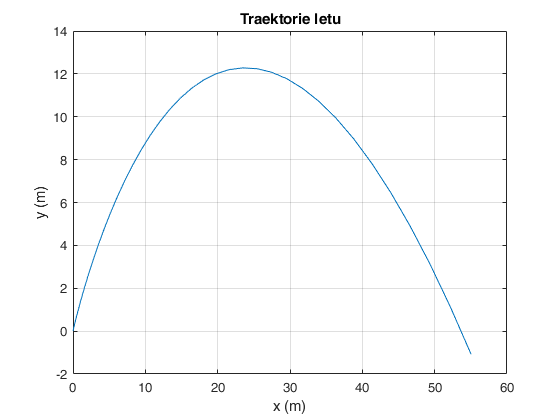

[t, vektor_velicin] = euler(@pohybova_funkce, 0, 100, vektor_velicin, 1e3); % numericke reseni soustavy

rx = vektor_velicin(:,1);
ry = vektor_velicin(:,2);
vx = vektor_velicin(:,3);
vy = vektor_velicin(:,4);
ax = vektor_velicin(:,5);
ay = vektor_velicin(:,6);

plot(rx, ry);
grid on;
xlabel('x (m)')
ylabel('y (m)')
title("Traektorie letu")

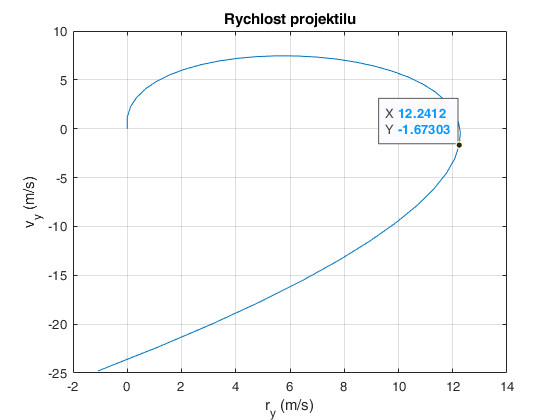


plot(ry, vy);
grid on;
xlabel('r_y (m/s)')
ylabel('v_y (m/s)')
title("Rychlost projektilu")

*Na délce kroku závisí, to jak moc "přejedu" do záporné polohy.*

Různé úhly:

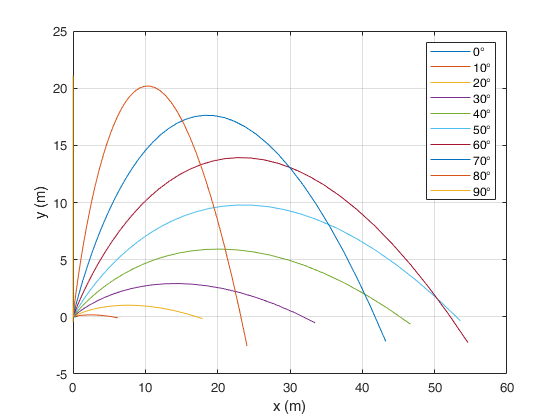

m = 0.5; % kg
uhel = 56; % °
F = 7; % N
pocatecni_vyska = 0;

a = F/m;
% uhel = (uhel/180)*pi; % převedení úhlu ve stupních na radiány

for u = 0:10:90
% for f = 5:2:15

% a = f/m;
uhel = (u/180)*pi; % převedení úhlu ve stupních na radiány


ax0 = a*cos(uhel);
ay0 = a*sin(uhel);

vx0 = 0;
vy0 = 0;

ry0 = pocatecni_vyska;
rx0 = 0;

vektor_velicin = [rx0, ry0, vx0, vy0, ax0, ay0];

[t, vektor_velicin] = euler(@pohybova_funkce, 0, 100, vektor_velicin, 1e3); % numericke reseni soustavy

rx = vektor_velicin(:,1);
ry = vektor_velicin(:,2);
vx = vektor_velicin(:,3);
vy = vektor_velicin(:,4);
ax = vektor_velicin(:,5);
ay = vektor_velicin(:,6);

warning('off','all')

plot(rx, ry);
hold on;
grid on;
xlabel('x (m)')
ylabel('y (m)')
legend("0°","10°","20°","30°","40°","50°","60°","70°","80°","90°");

end
hold off;

Nejlepší úhel:

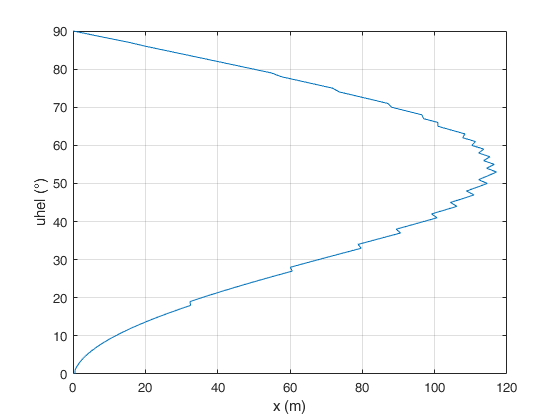

m = 0.5; % kg
F = 9; % N
pocatecni_vyska = 0;

a = F/m;

vysledky_rx = zeros(1,91);

for u = 0:90

uhel = (u/180)*pi; % převedení úhlu ve stupních na radiány

ax0 = a*cos(uhel);
ay0 = a*sin(uhel);

vx0 = 0;
vy0 = 0;

ry0 = pocatecni_vyska;
rx0 = 0;

vektor_velicin = [rx0, ry0, vx0, vy0, ax0, ay0];

[t, vektor_velicin] = euler(@pohybova_funkce, 0, 100, vektor_velicin, 1e3); % numericke reseni soustavy

rx = vektor_velicin(:,1);
ry = vektor_velicin(:,2);
vx = vektor_velicin(:,3);
vy = vektor_velicin(:,4);
ax = vektor_velicin(:,5);
ay = vektor_velicin(:,6);

vysledky_rx(u+1) = max(rx);

end

plot(vysledky_rx,0:90);
grid on;
xlabel('x (m)')
ylabel('uhel (°)')


[rx_max,uhel_max] = max(vysledky_rx)

rx_max = 117.1012

uhel_max = 54

Za dobrovolný úkol zkusit udělat RL obvod a nějak hezky ho vyrkeslit v čase. Bude to asi nějaká exponenciála žejo.. 

zadaný je např:

U0= 10

L = 1e-3

R = 1